% extended kalman filter example 2
% tracking of a robot
% states = (position x, position y, orientation theta) = (x, y, theta)'
% control inputs = (commanded velocity, steering angle) =  (v, alpha)'

### **Clearing**

clear variables; close all; clc;
addpath('../utilities');

### **Model**

% landmarks information
landmarks = [5 10; 10 5; 15 15; 20 5; 15 10; 10 14; 23 14; 25 20; 10 20]';
% overwrite to set only first landmark
% landmarks = landmarks(:, 1);
dim_lm = size(landmarks, 2);

% dimensions
dim_x = 3;
dim_z = 2 * dim_lm;
dim_u = 2;

% time step [s]
dt = 0.5;

% robot information
wheelbase = 0.5;
robot_pos = [2, 6, 0.3]';

% sensor information
range_std = 0.3;
bearing_std = 0.1;

% measure noise covariance
diag_values = repmat([range_std^2 bearing_std^2], 1, size(landmarks, 2));
R = diag(diag_values);
  
% (non linear) state transition function
f = @(x, u) bicycle_kinematic_move(x, u, dt, wheelbase);

% (non linear) measurement function
h = @(x) h_robot(x, landmarks);

### **Filter initialization**

x0 = [2, 6, 0.3]';
P0 = diag([0.1 0.1 0.1]);

% mean
x = x0;

% covariance
P = P0;

### **Filter settings**

% number of input commands
n = 500;

% data structures
track = zeros(dim_x, n);
x_posterior = zeros(dim_x, n);
P_posterior = cell(1, n);
x_prior = zeros(dim_x, n);
P_prior = cell(1, n);
x_posterior_mat = zeros(dim_x, n);
P_posterior_mat = cell(1, n);

### **Input commands**

commands = ones(dim_u, n);
commands(:, 1:n) = commands(:, 1:n).*[1.1 0.01]';

std_velocity = 0.1;
std_stearing_angle = deg2rad(1);

### **Filtering**

% define weighted mean angle function
% wma = @(angles, weights) atan2(sin(angles) * weights', cos(angles) * weights');
    
% filtering
for tt = 1 : n
    % Get current command
    u = commands(:, tt);
    
    % simulate new robot position (x, y, theta)
    robot_pos = bicycle_kinematic_move(robot_pos, u, dt, wheelbase);
        
    % build observations/measures
    z = robot_measure(robot_pos, landmarks, range_std, bearing_std, dim_z);
    
    % linearization
    F = robot_move_jx(x, u, wheelbase, dt);
    V = robot_move_ju(x, u, wheelbase, dt);
    M = diag([(std_velocity * u(1))^2 std_stearing_angle^2]);
    H = nan(dim_z, dim_x);
    for ii = 1 : dim_lm
        dist = norm(landmarks(:, ii) - x(1:2));
        hyp = dist^2;
        H(2*ii-1:2*ii, :) = [-(landmarks(1, ii) - x(1))/dist, -(landmarks(2, ii) - x(2))/dist, 0; (landmarks(2, ii) - x(2))/hyp,  -(landmarks(1, ii) - x(1))/hyp, -1];
    end
        
    % predict
    x = f(x, u);
    P = F*P*F' + V*M*V';
    
    % saving
    x_prior(:, tt) = x;
    P_prior{tt} = P;
    
    % update     
    K = P*H' / (H*P*H' + R);
    e = z - h(x);
    x = x + K*e;
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
        
    % saving
    track(:, tt) = robot_pos;
    x_posterior(:, tt) = x;
    P_posterior{tt} = P;
end

### **Plots**

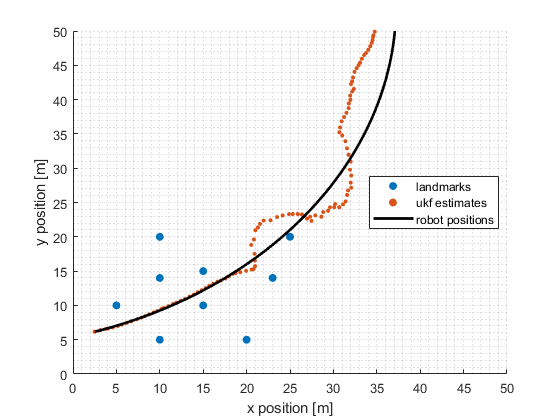

mP_posterior = cell2mat(P_posterior);
mP_prior = cell2mat(P_prior);
cols = 1:size(mP_posterior, 2);
cols = cols(mod(cols,3) ~= 0);
prob = normcdf(6)-normcdf(-6);

figure; hold on; grid minor;
scatter(landmarks(1, :), landmarks(2, :), 'filled');
scatter(x_posterior(1, :), x_posterior(2, :), 10, 'filled');
plot(track(1, :), track(2, :), 'k', 'LineWidth', 2);
xlabel('x position [m]'); ylabel('y position [m]'); xlim([0 50]); ylim([0 50]);
legend('landmarks', 'ukf estimates', 'robot positions', 'location', 'best')

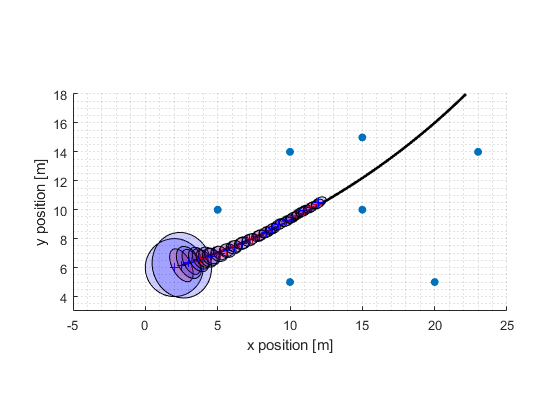

figure; hold on; grid minor; axis equal
xlabel('x position [m]'); ylabel('y position [m]'); xlim([-5 25]); ylim([3 18]);
scatter(landmarks(1, :), landmarks(2, :), 'filled');
plot(track(1, :), track(2, :), 'k', 'LineWidth', 2);
plot_covariance_ellipse(x0(1:2), P0(1:2, 1:2), prob, 'b', '');
for ii = 1 : 1 : 20
    plot_covariance_ellipse(x_posterior(1:2, ii), mP_posterior(1:2, cols(2*ii-1:2*ii)), prob, 'r', '');
    plot_covariance_ellipse(x_prior(1:2, ii), mP_prior(1:2, cols(2*ii-1:2*ii)), prob, 'b', '');
end